# Beattie - Assignment 1 of 2

## 4.1 - Geometric construction of the Forward Euler method

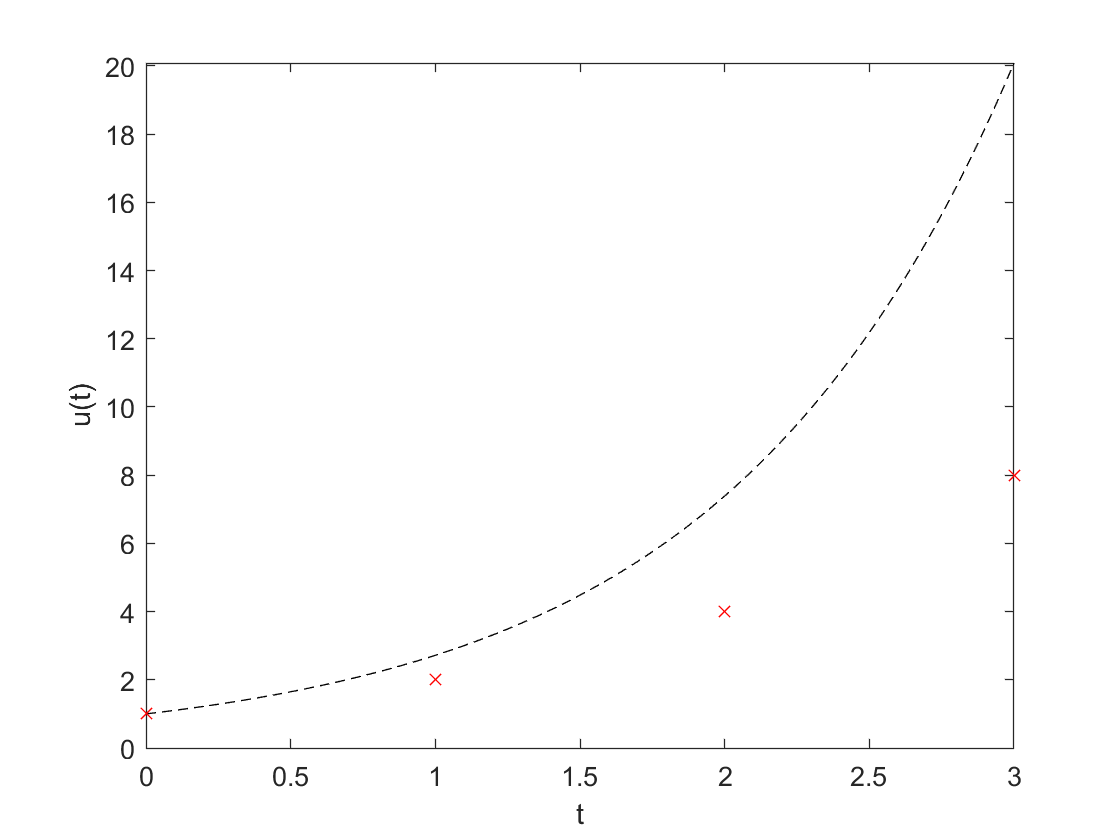

% Geometric Construction of the Forward Euler Method for u' = u
a = 0; b = 3;
dudt = @(u) u;
u_calc = @(t) exp(t);

u = zeros(4, 1);
u(1) = 1;
dt = 1;

for i = 1:3
    u(i+1) = u(i) + dt*dudt(u(i));
end


tP = [0 1 2 3];
time = linspace(a, b, 100);
u_true = u_calc(time);
plot(time, u_true, 'k--', tP, u, 'rx');
xlabel('t');
ylabel('u(t)');

## 4.2 - Make test functions for the Forward Euler method

test_ode_FE_1();
test_ode_FE_2();

## 4.4 Find an appropriate time step; logistic model

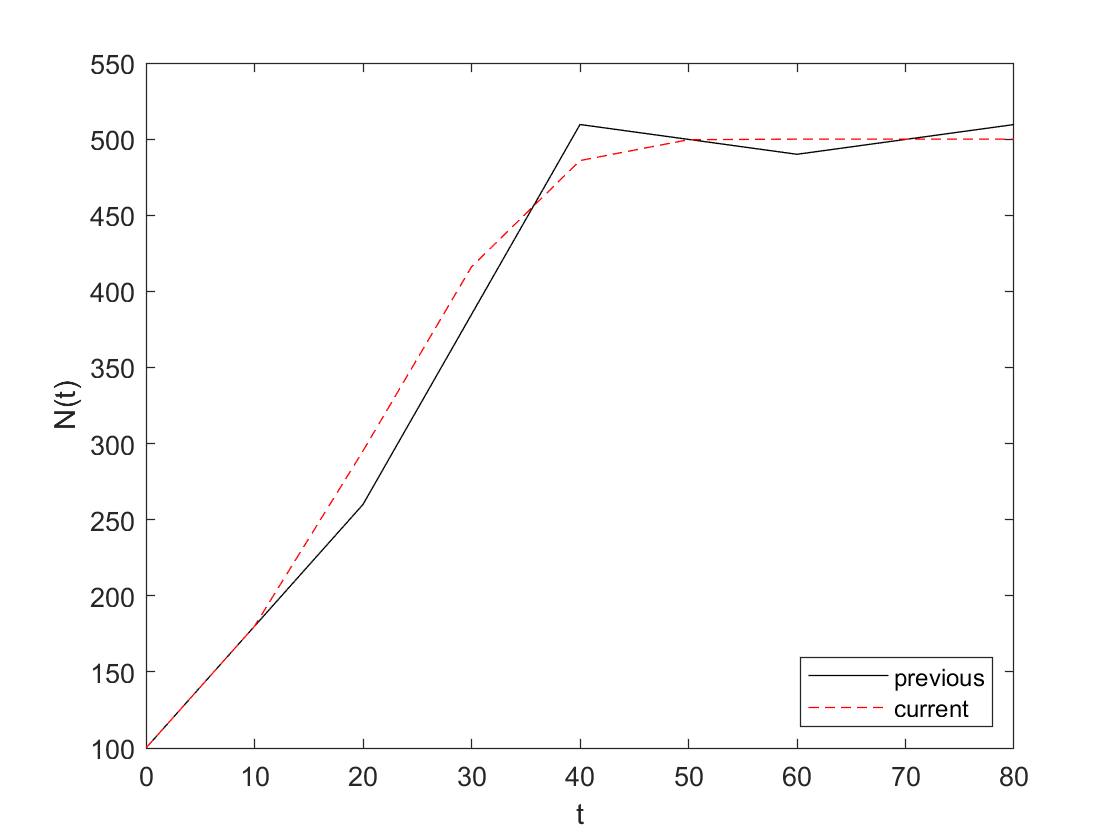

Previous timestep was: 10.000 


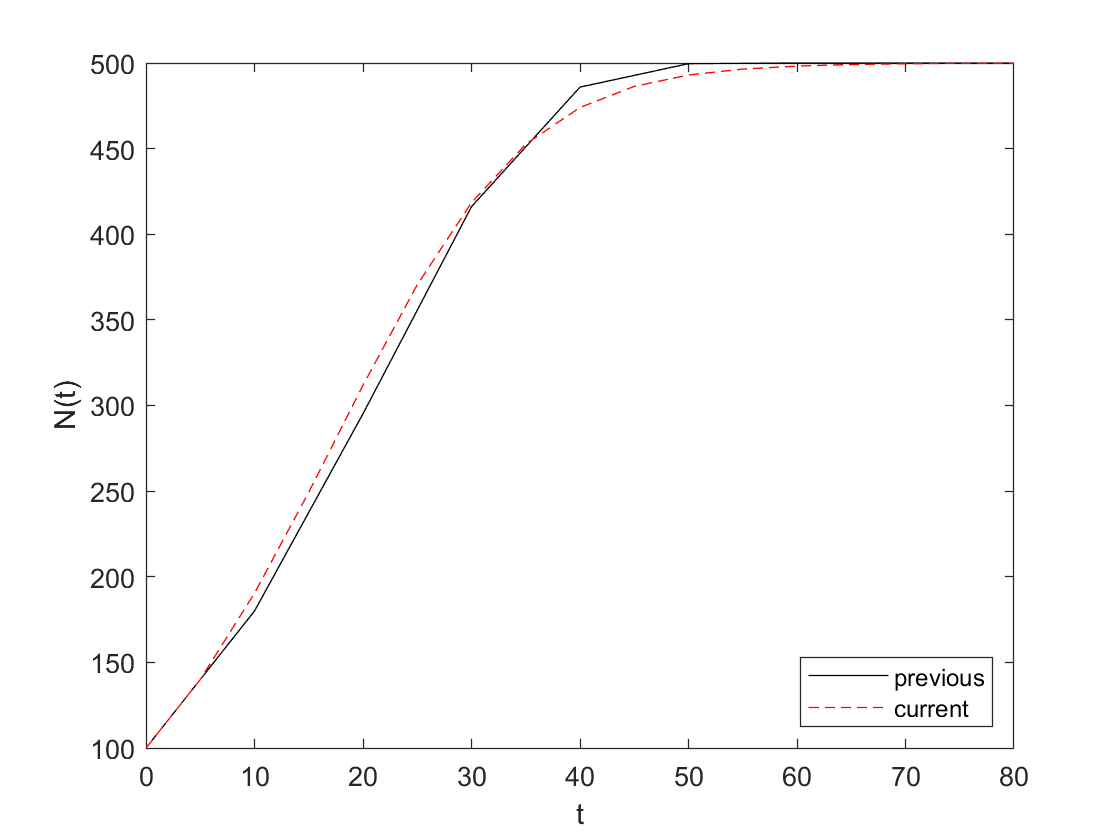

Previous timestep was: 5.000 


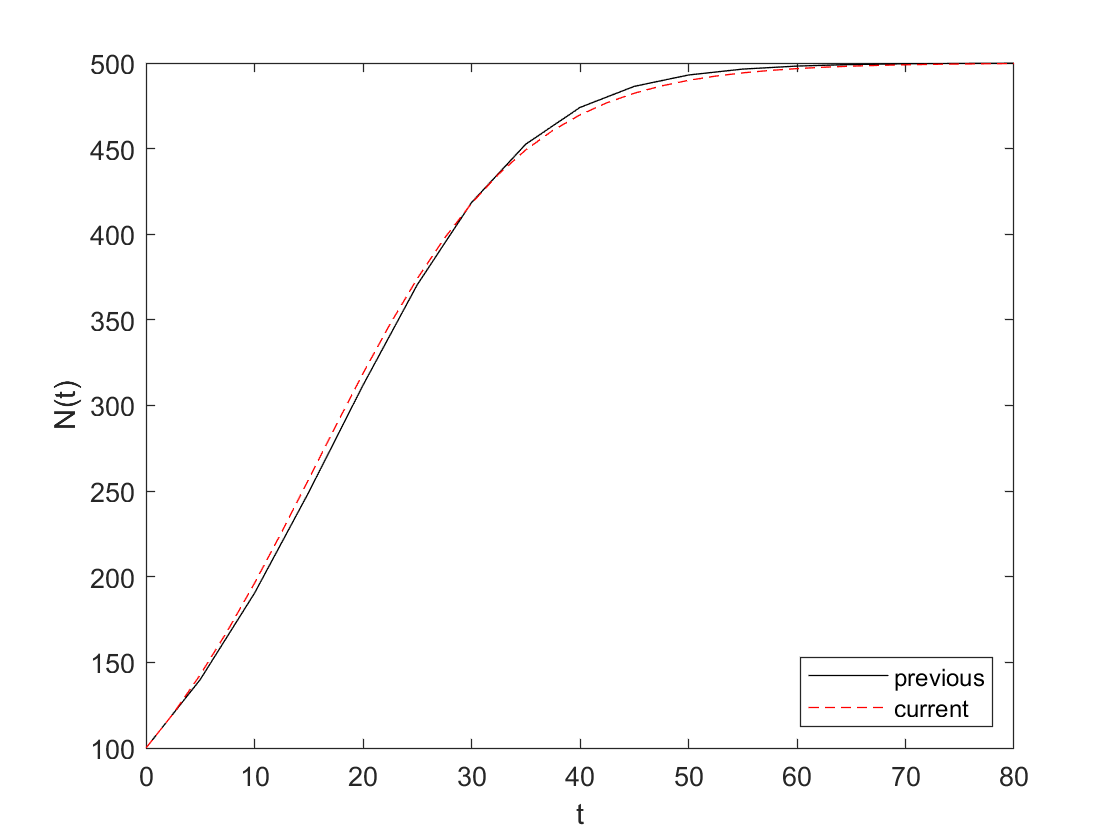

Previous timestep was: 2.500 


% Repetition of solution from last task
% Extension of logistic.m found on page 99

dt = 20;
T = 80;
f = @(u,t) 0.1*(1-u/500)*u;

U_0 = 100;

[u, t] = ode_FE(f, U_0, dt, T);

k = 1;
while true
    dt_k = 2^(-k)*dt;
    [u_current, t_current] = ode_FE(f, U_0, dt_k, T);
    graph_result(t,u,t_current,u_current, dt_k);
    fprintf("Previous timestep was: %0.3f \n", dt_k)
    if (strcmp(input("Continue with a higher dt value [y/n]? ",'s'),'y'))
       u = u_current;
       t = t_current;
       k = k + 1;
    else 
        break; % The interval is okay so we're stopping the loop
    end

end

## 4.5 - Find an appropriate time step; SIR model

Current timestep: 24


Current timestep: 12


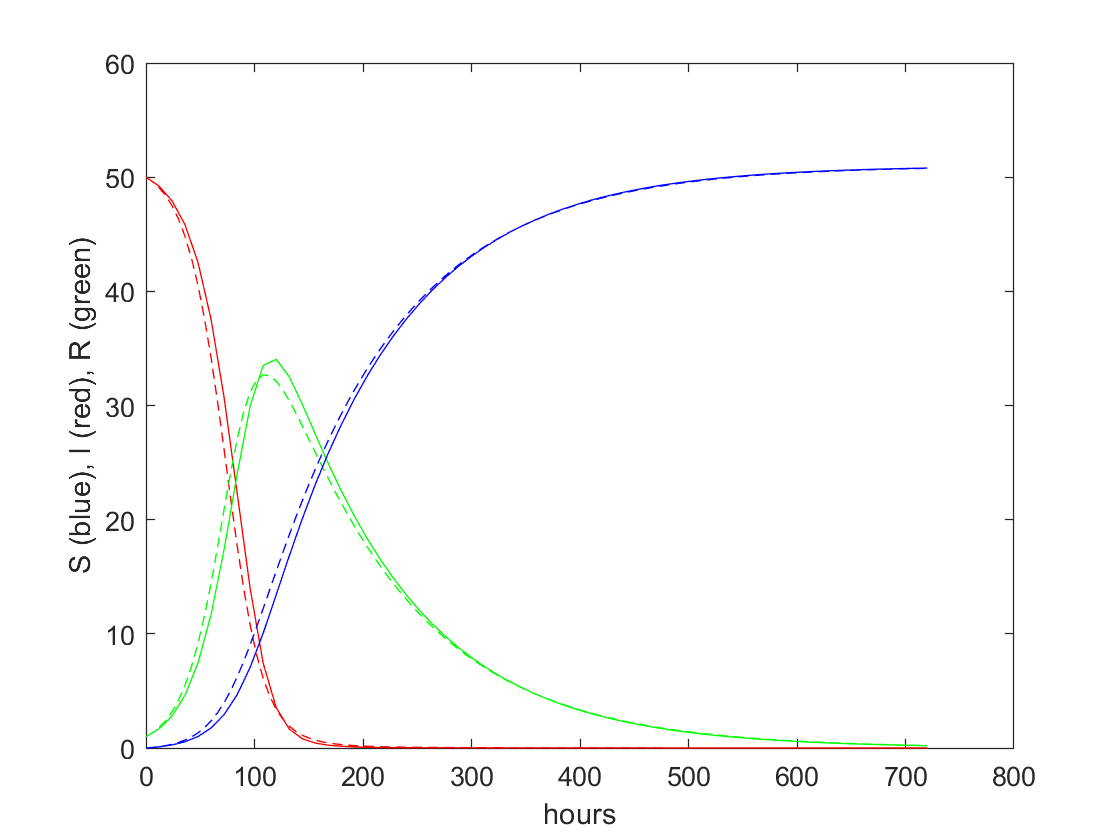

Current timestep: 6


demo_SIR

## 4.6 - Model an adaptive vaccination campaign

beta: 0.000325521


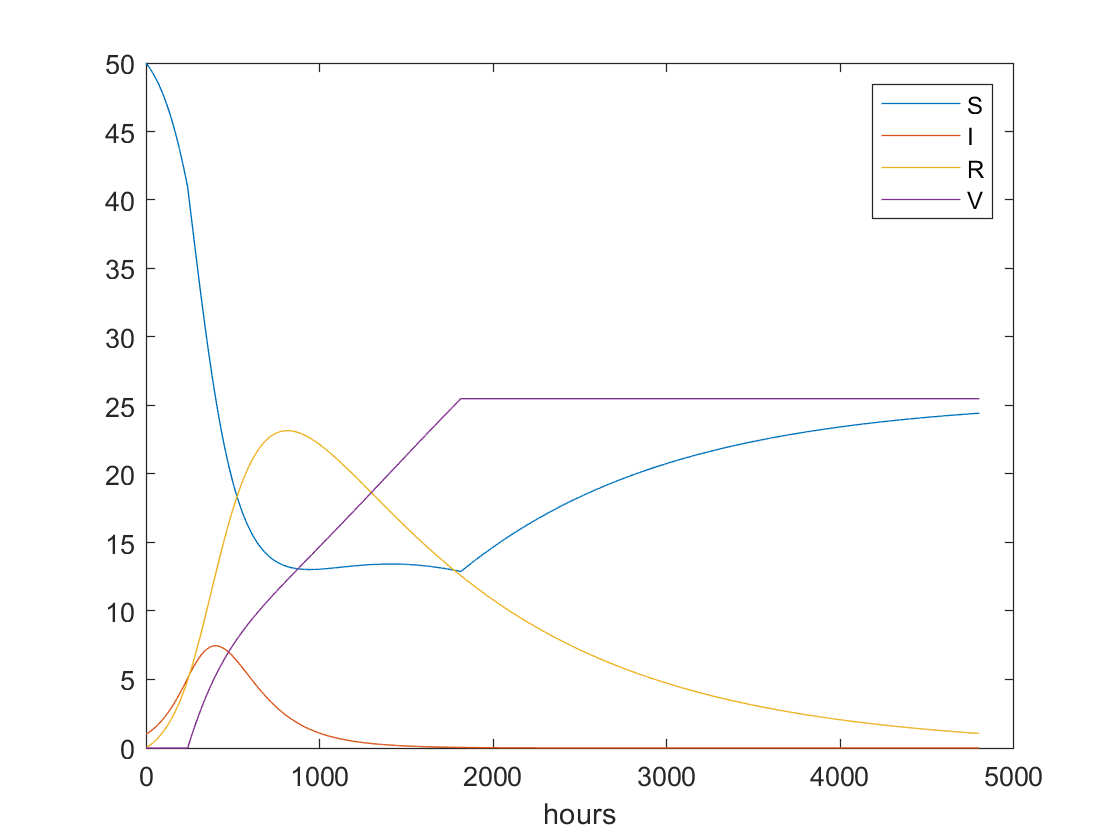

SIRV_p_adapt

## 4.8 - Refactor a flat program

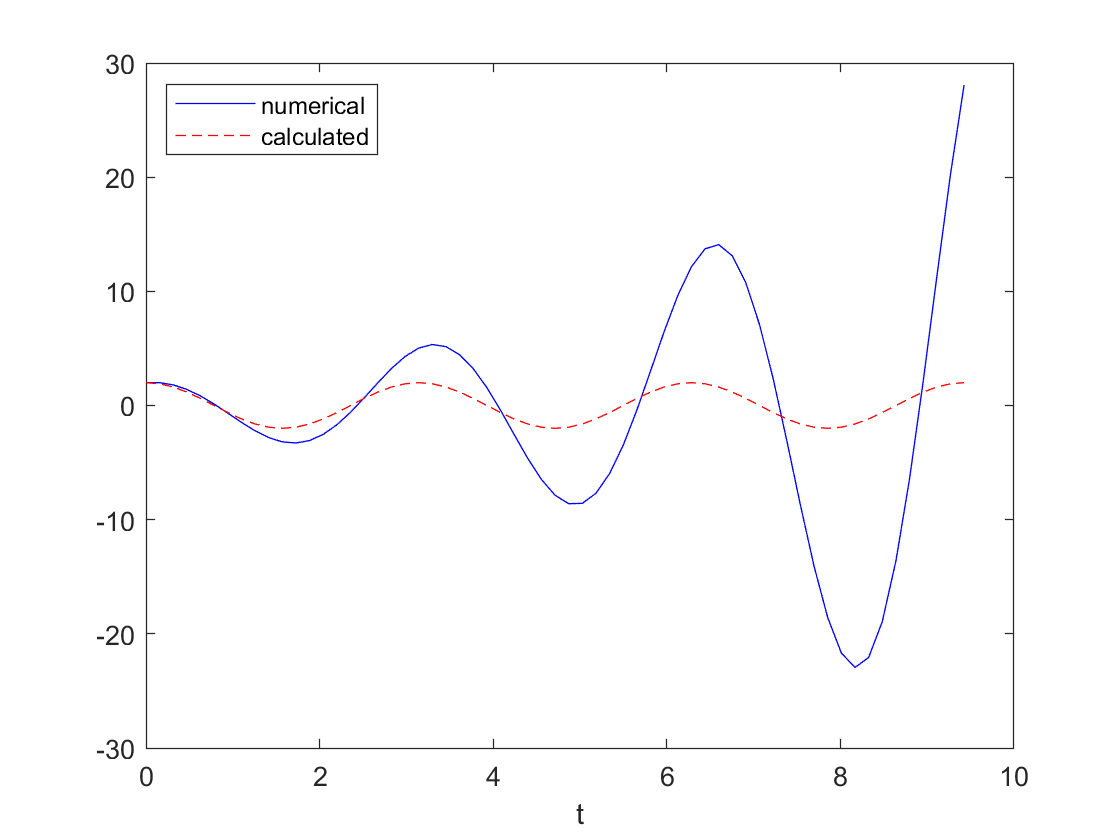

demo_osc_FE

## 4.9 - Simulate oscillations by a general ODE solver

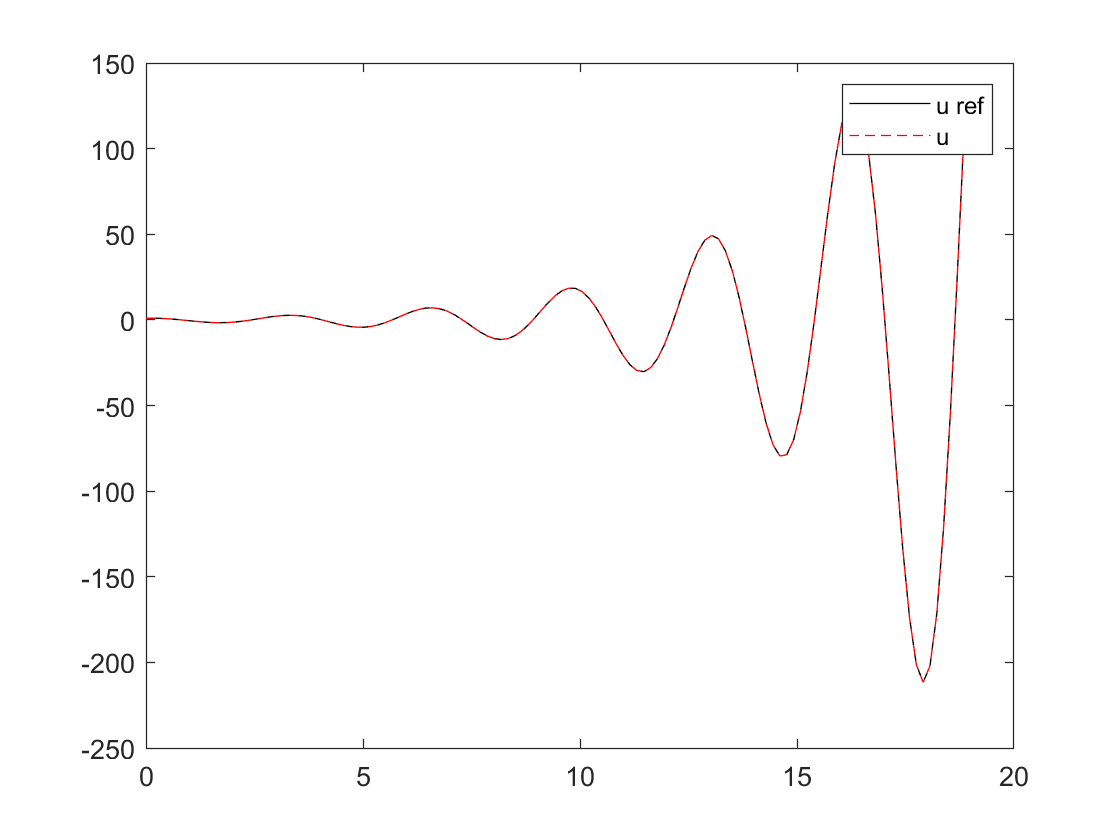

test_osc_ode_FE

# Functions  (Must Be at the End)

## Utility Graphing Function

function graph_result(t,u,t_current, u_current,dt_k)
    figure
    plot(t,u,'k',t_current,u_current,'r--')
    legend('previous','current','Location','southeast')
    xlabel('t');
    ylabel('N(t)');
    saveas(gcf,sprintf("output_logistic_dt_%d.png",dt_k))
end

## 4.2 Tests For Forward Euler Method


function test_ode_FE_1()
    function res = f(u, ~)
        res = u;
    end
    u_calc = [1 2 4 8];
    T = 3;
    dt = 1;
    U_0 = 1.0;
    [u, ~] = ode_FE(@f, U_0, dt, T);
    tol = 1E-14;
    for i = 1:length(u_calc)
        err = abs(u_calc(i) - u(i));
        assert(err < tol, 'i=%d, err=%g', i, err);
    end
end
        
function test_ode_FE_2()
    function res = f(u, ~)
        r = 1;
        res = r*u;
    end
    function res = u_calc(u_init, dt, n)
        r = 1;
        res = u_init * (1 + r * dt)^n;
    end
    T = 3;
    dt = 0.1;
    U_0 = 1.0; 

    [u, ~] = ode_FE(@f, U_0, dt, T);
    tol = 1E-12; 
    for n = 1:length(u)
        err = abs(u_calc(U_0, dt, n-1) - u(n));
        assert(err < tol, 'n=%d, err=%g', n, err);
    end
end

## 4.5 - Demo SIR Functions

function demo_SIR()
    % Find appropriate time step for an SIR model
    function res = f(u,~)
        beta = 10/(40*8*24);
        gamma = 3/(15*24);        
        S = u(1);
        I = u(2);
        R = u(3);
        res = [-beta*S*I beta*S*I - gamma*I gamma*I];
    end
    
    dt = 48.0;   % 48 hours
    D = 30;      % for D days
    N_t = floor(D*24/dt);    % Number of hours total
    T = dt*N_t;              % Simulation end time
    U_0 = [50 1 0];
    
    [u_old, t_current] = ode_FE(@f, U_0, dt, T);
    
    S_current = u_old(:,1);
    I_current = u_old(:,2);
    R_current = u_old(:,3);
    k = 1;
    while true
        dt_k = 2^(-k)*dt;
        [u_new, t_new] = ode_FE(@f, U_0, dt_k, T);
        S_new = u_new(:,1);
        I_new = u_new(:,2);
        R_new = u_new(:,3);

        plot(t_current, S_current, 'r-', t_new, S_new, 'r--',...
             t_current, I_current, 'g-', t_new, I_new, 'g--',...
             t_current, R_current, 'b-', t_new, R_new, 'b--');
        xlabel('hours'); 
        ylabel('S (blue), I (red), R (green)');
        fprintf('Current timestep: %g\n', dt_k);
        if ~strcmp(input("Continue with a higher dt value [y/n]? ",'s'), 'y')
            break;
        end
        S_current = S_new;
        R_current = R_new;
        I_current = I_new;
        t_current = t_new;
        k = k + 1;
    end
end

## 4.6 - Model an adaptive vaccination campaign

function SIRV_p_adapt()
    % Time-dependent vaccination. 
    % Time unit: 1 h
    
    function res = p(t, n)
        if ( V(n) < 0.5 * ( S(1) + I(1) ) && t > Delta * 24)
            res = p_0;
        else
            res = 0;
        end
    end
    
    beta = 10 /( 40 * 8 * 24 );
    beta = beta/4;        % Reduce beta
    fprintf('beta: %g\n', beta);
    gamma = 3/(15*24);
    dt = 0.1;             % 6 minute simulation
    D = 200;              % for D days
    N_t = floor(D*24/dt); % Calcuated hours
    nu = 1/(24*50);       % Average loss of immunity
    Delta = 10;           % Start campaign in Delta days
    p_0 = 0.001;

    t = linspace(0, N_t*dt, N_t+1);
    S = zeros(N_t+1, 1);
    I = zeros(N_t+1, 1);
    R = zeros(N_t+1, 1);
    V = zeros(N_t+1, 1);

    S(1) = 50;
    I(1) = 1;
    R(1) = 0;
    V(1) = 0;

    epsilon = 1e-12;
    % Iterate equations 
    for n = 1:N_t
        S(n+1) = S(n) - dt*beta*S(n)*I(n) + dt*nu*R(n) - dt*p(t(n),n)*S(n);
        V(n+1) = V(n) + dt*p(t(n),n)*S(n);
        I(n+1) = I(n) + dt*beta*S(n)*I(n) - dt*gamma*I(n);
        R(n+1) = R(n) + dt*gamma*I(n) - dt*nu*R(n);
        loss = (V(n+1) + S(n+1) + R(n+1) + I(n+1)) - (V(1) + S(1) + R(1) + I(1));
        if loss > epsilon
            fprintf('loss: %g\n', loss);
        end
    end
    
    figure();
    plot(t, S, t, I, t, R, t, V);
    legend('S', 'I', 'R', 'V', 'Location', 'northeast');
    xlabel('hours');
    saveas(gcf,"output_vaccination_campaign.png")
end

## 4.8 - OSC_FE Function

function [u, v, t] = osc_FE(X_0, omega, dt, T)
    N_t = floor(T/dt);
    u = zeros(N_t+1, 1);
    v = zeros(N_t+1, 1);
    t = linspace(0, N_t*dt, N_t+1);

    % Init
    u(1) = X_0;
    v(1) = 0;

    % Iterate in time
    for n = 1:N_t
        u(n+1) = u(n) + dt*v(n);
        v(n+1) = v(n) - dt*omega^2*u(n);
    end
end

function demo_osc_FE()
    omega = 2;
    P = 2*pi/omega;
    dt = P/20;
    T = 3*P;
    X_0 = 2;
    [u, ~, t] = osc_FE(X_0, omega, dt, T);

    plot(t, u, 'b-', t, X_0*cos(omega*t), 'r--');
    legend('numerical', 'calculated', 'Location', 'northwest');
    xlabel('t');
end

## 4.9 - OSC_FE 2 file

function test_osc_ode_FE()
    function res = f(sol, ~)
        u = sol(1);
        v = sol(2);
        res = [v -omega^2*u];
    end
    
    % Set and compute problem dependent parameters
    omega = 2;   
    X_0 = 1;
    number_of_periods = 6;
    time_intervals_per_period = 20;

    P = 2*pi / omega;                   % one period
    dt = P/time_intervals_per_period;   % step       
    T = number_of_periods*P;            % Final time
    U_0 = [X_0 0];                      % Init
       
    file_name = 'osc_FE_data';
    osc_FE_2file(file_name, X_0, omega, dt, T);    
    
    [sol, t] = ode_FE(@f, U_0, dt, T);
    u = sol(:,1);
       
    infile = fopen(file_name, 'r');
    u_ref = fscanf(infile, '%f');
    fclose(infile);
        
    tol = 1E-5;
    for n = 1:length(u)
        err = abs(u_ref(n) - u(n));
        assert(err < tol, 'n=%d, err=%g', n, err);
    end
    
    % Choose to also plot, just to get a visual impression of u
    plot(t, u_ref, 'k-', t, u, 'r--');
    legend('u ref', 'u');
end

function osc_FE_2file(filename, X_0, omega, dt, T)
    N_t = floor(T/dt);
    u = zeros(N_t+1, 1);
    v = zeros(N_t+1, 1);

    % Init
    u(1) = X_0;
    v(1) = 0;
    
    outfile = fopen(filename, 'w');
    fprintf(outfile,'%10.5f\n', u(1));

    % Iterate equations
    for n = 1:N_t
        u(n+1) = u(n) + dt*v(n);
        v(n+1) = v(n) - dt*omega^2 * u(n);
        fprintf(outfile,'%10.5f\n', u(n+1));
    end
    fclose(outfile);  
end